%clear all; clc;

**Read Rosbag file**

bag= rosbag('RRC-2020-07-08-12-06.bag');
DrivePointTopic= select(bag, 'Topic', '/drive_points');
DrivePointMsg = readMessages(DrivePointTopic,'DataFormat','struct');
path_x_all= cellfun(@(m) double(m.X),DrivePointMsg);
path_y_all= cellfun(@(m) double(m.Y),DrivePointMsg);

% PointCloudTopic= select(bag, 'Topic', '/point_clouds');
% PointCloudMsg= readMessages(PointCloudTopic);

TeensyTopic= select(bag, 'Topic', '/teensy_read');
TeensyMsg = readMessages(TeensyTopic,'DataFormat','struct');
speed= cellfun(@(m) double(m.SpeedWheel),TeensyMsg);

HeadTopic= select(bag, 'Topic', '/gyro_angle');
HeadMsg = readMessages(HeadTopic,'DataFormat','struct');
theta= cellfun(@(m) double(m.Data), HeadMsg);

SteerTopic= select(bag, 'Topic', '/cmd_steering_angle');
SteerMsg= readMessages(SteerTopic, 'DataFormat', "struct");
SteerAngle_org= cellfun(@(m) double(m.SteeringAngle), SteerMsg);


**Convert data into double**

%point cloud
% pc_list=[];
% for i= 1:20:length(PointCloudMsg)
%     pc_list= [pc_list; PointCloudMsg{i,1}.readXYZ];
% end

% path center point
index_NotNaN= find(~isnan(path_x_all));
path_x= path_x_all(index_NotNaN);
path_y= path_y_all(index_NotNaN);

center_smooth= movmean([path_x,path_y], 300);
center_dwnsize= center_smooth(1:10:end,:);

% downsize the speed
speed_dwn= speed(1: length(speed)/length(center_smooth):end)./3.6;


% downsize the oritentation
theta_dwn= deg2rad(theta(1: length(theta)/length(center_smooth):end));


i_NotNaN= find(~isnan(SteerAngle_org));
SteerAngle= SteerAngle_org(i_NotNaN);

s_rrc=0;
s_rrc_list=[];
for i= 1:length(center_dwnsize)-1
    dx= center_dwnsize(i+1,1)- center_dwnsize(i,1);
    dy= center_dwnsize(i+1,2)- center_dwnsize(i,2);
    s_rrc= s_rrc+ sqrt(dx^2+dy^2);
    s_rrc_list=[s_rrc_list; s_rrc];
end

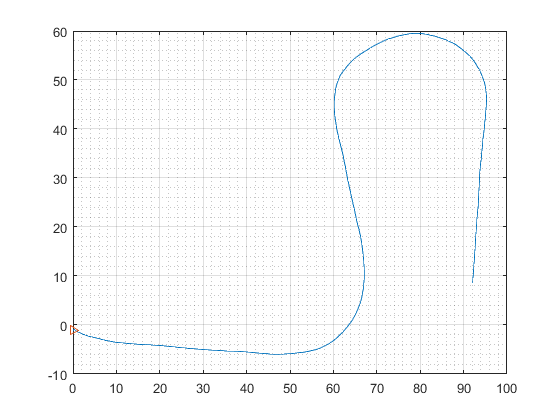

% close all;
figure;
plot(center_dwnsize(1:358,1), center_dwnsize(1:358,2), 'linewidth', 1.0, "LineStyle","-");
hold on;
plot(center_smooth(1,1), center_smooth(1,2), 'marker', ">");
% hold on;
% scatter(pc_list(1:10:end,1), pc_list(1:10:end,2));
hold off;
grid on; grid minor;

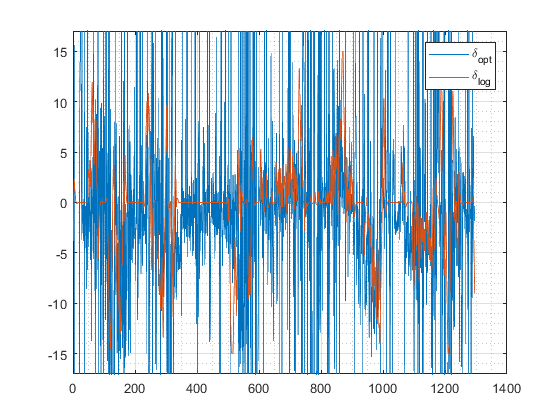

num= 1: s_rrc/length(SteerAngle): 1295;
figure;
plot(num, SteerAngle(1:length(num)))
ylim([-17, 17])
hold on;
plot(u.x_Delta(plot_num)*(180/pi))
hold off;
grid on; grid minor;
legend('\delta_{opt}', '\delta_{log}')

% figure();
% plot(pc_list(1:10:466712/1.98,1), pc_list(1:10:466712/1.98,2));

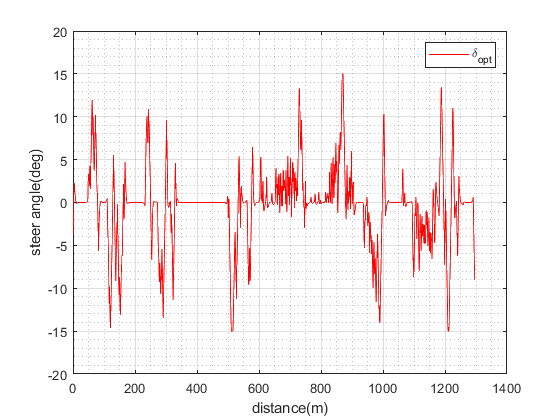

figure;
plot(u.x_Delta(plot_num)*(180/pi), 'red')
grid on; grid minor;
legend('\delta_{opt}')
xlabel('distance(m)')
ylabel('steer angle(deg)')